# Research 3

Explore how SVD (i.e., PCA) can help figure out the "intrinsic dimension" for discrete data on the following Klein Bottle ( Ans = 2 ):

>> [u,v]=meshgrid(linspace(0,2*pi)); 

>> x = (2*cos(v)+1).*cos(u); y = (2*cos(v)+1).*sin(u); z = 2*sin(v).*cos(u/2); w = 2*sin(v).*sin(u/2); 

>> mesh(x,y,z) 

Propose possible ways (i.e., pseudocode) to deal with d-dimensional data embedded in R^D with d<<D. Also discuss computational cost.

#### Genearting raw data

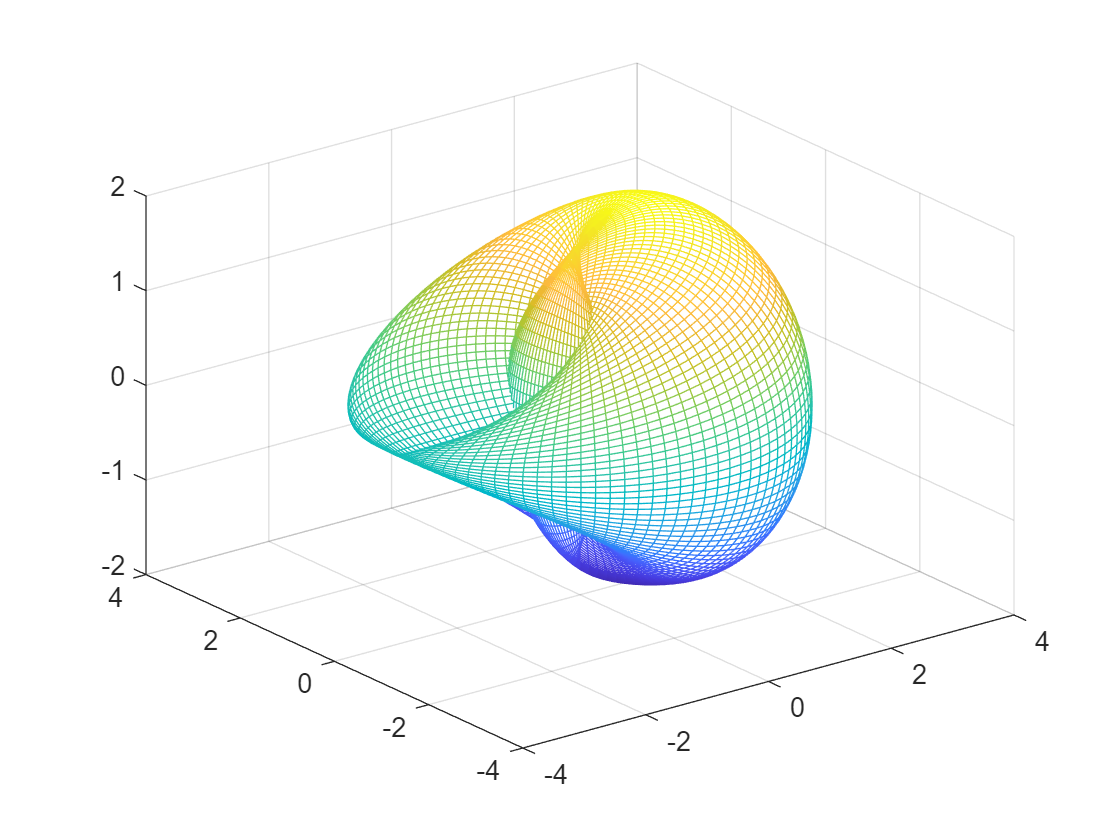

[u,v]=meshgrid(linspace(0,2*pi)); 
x = (2*cos(v)+1).*cos(u); 
y = (2*cos(v)+1).*sin(u); 
z = 2*sin(v).*cos(u/2);
w = 2*sin(v).*sin(u/2); 
mesh(x,y,z)

#### Converting x, y, z to a 10000 by 3 matrix

A0 = zeros(10000, 3);
for inx = 1:100
    i_start = 1 + 100*(inx - 1);
    i_end = 100*inx;
    A0(i_start:i_end, 1) = x(:, inx);
    A0(i_start:i_end, 2) = y(:, inx);
    A0(i_start:i_end, 3) = z(:, inx);
end

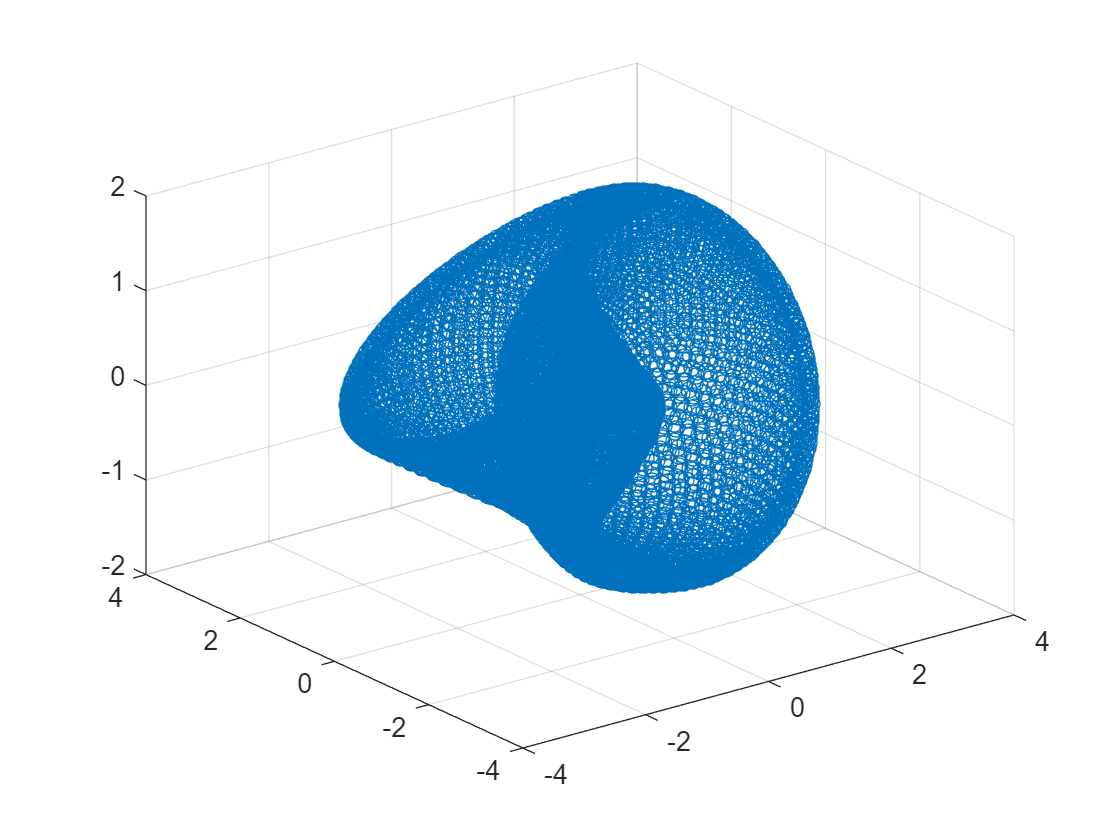

scatter3(A0(:, 1), A0(:, 2), A0(:, 3))

#### SVD

Singular value decomposition and verifying the result by U*S*V'

[U, S, V] = svd(A0);
A1 = U * S * V';
scatter3(A1(:, 1), A1(:, 2), A1(:, 3))

Check **Singular values **of each dimension after SVD

S

S =   124.3101         0         0
         0  123.0731         0
         0         0   99.9950
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


Since all 3 singular values are big, I cannot figure out why the intrinsic dimension is 2.

#### Principal component analysis (PCA)

[coeff,score,latent,tsquared,explained] = pca(A0);
explained

explained =    38.0609
   37.3098
   24.6293


As we can see, the percent variability explained by principal components of all 3 dimensions is big and similar, so I also cannot get the reault: the intrinsic dimension of A0 is 2.

#### Propose possible ways (i.e., pseudocode) to deal with d-dimensional data embedded in R^D with d<<D

**Basic idea**: Just like KNN (k-nearest neighbors) model, we can reduce the dimension of points in R^D to d by dealing with a small local part each step.

**Pseudocode**:

Assume there are n points and the whole points form a set N,

D(n by n matrix) <- calculate the distance between each point pair in R^D

for x = 1:len(N)

    x <- Select 1 point from N randomly

    C1 <- Find all nearest neighbors of point x which the distance less than a specific value

    Reduce the dimension of cluster C1 to R^d by PCA

    N <- N - C1  (remove cluster C1 from N)

end

**Computational cost**:

The computional cost of D is O(n^2), PCA of n points from R^D is O(n*D^2). Therefore the total comuptational cost is O(n^2 + n*D^2).